Theodore Janson (260868223)

Lab Assignment 2

ECSE 403, Prof. Caines

October 3rd, 2020

The main goal of this assignment is to review some concepts from the linear control course(ECSE 307), and to become familiar with some useful tools in MATLAB which helps us in designing and implementing controllers. Following concepts are covered in this assignment: response of a second order system, root-locus diagram, state space representation, pole-zero plots, and stability of uncontolled dynamics. 

The final goal of this lab is to model and control an inverted pendulum system. In that system the input is applied to a DC motor connected to a cart-pole. The first step to model the whole system is to model the DC motor. We saw the (approximate) model of the DC motor in lab 1 as: 

JmØ'' + (b+KtKe/Ra)Ø' = (Kt/Ra)Va

Constants					

Jm = 0.01; %kgm^2 , inertia of the rotor and shaft
b = 0.001; %Nmsec , viscous friction coefficient
Ke = 0.02; %Vsec  , back emf constant
Kt = 0.02; %Nm/A  , motor torque constant
Ra = 10;   %Ω     , armature resitance


4.1 Proportional Controller

*1.  Consider the transfer function θ(s)/va (s)  in lab assignment 1 as open loop system. Suppose we are using a proportional gain with a unity feedback loop. Using the standard form of second order systems: *

*ωn^2 / (s^2 + 2ζωns + ωn2^ 2)*

*find the parameters ωn, ζ of the closed loop system as a function of proportional con- troller(gain) K. [5 marks] *

Using the coefficients for  θ' and va, 

a1 = (b+(Kt*Ke)/Ra)/Jm; %divide equation Jm to get unity coefficient for θ''
b0 = Kt / (Ra*Jm);

We can then define the transfer function using polynomial coefficients: 

syms s
G = b0 / (s^2 + a1*s);
G = simplify(G)

$$G = \frac{25}{s\,\left(125\,s+13\right)}$$

Closed loop transfer function of unity feedback

syms G1(k)
G1(k) = G*k / (1 + G*k);
G1(k) = simplify(G1(k))

$$G1(k) = \frac{25\,k}{125\,s^{2}+13\,s+25\,k}$$


wn = 25*k/125

$$wn = \frac{k}{5}$$

damping = (13/125)*(1/(2*wn))

$$damping = \frac{13}{50\,k}$$

2. For the closed loop system in Question 1, plot the the roots of the closed loop system for proportional gains K ∈ [0.01, 0.1, 1, 10, 100, 103] in one plot to see the movement of poles as a function of proportional gain K.[5 marks]

K = [0.01 0.1 1 10 100 1000]

K = 	1.0e+03 *

    0.0000    0.0001    0.0010    0.0100    0.1000    1.0000


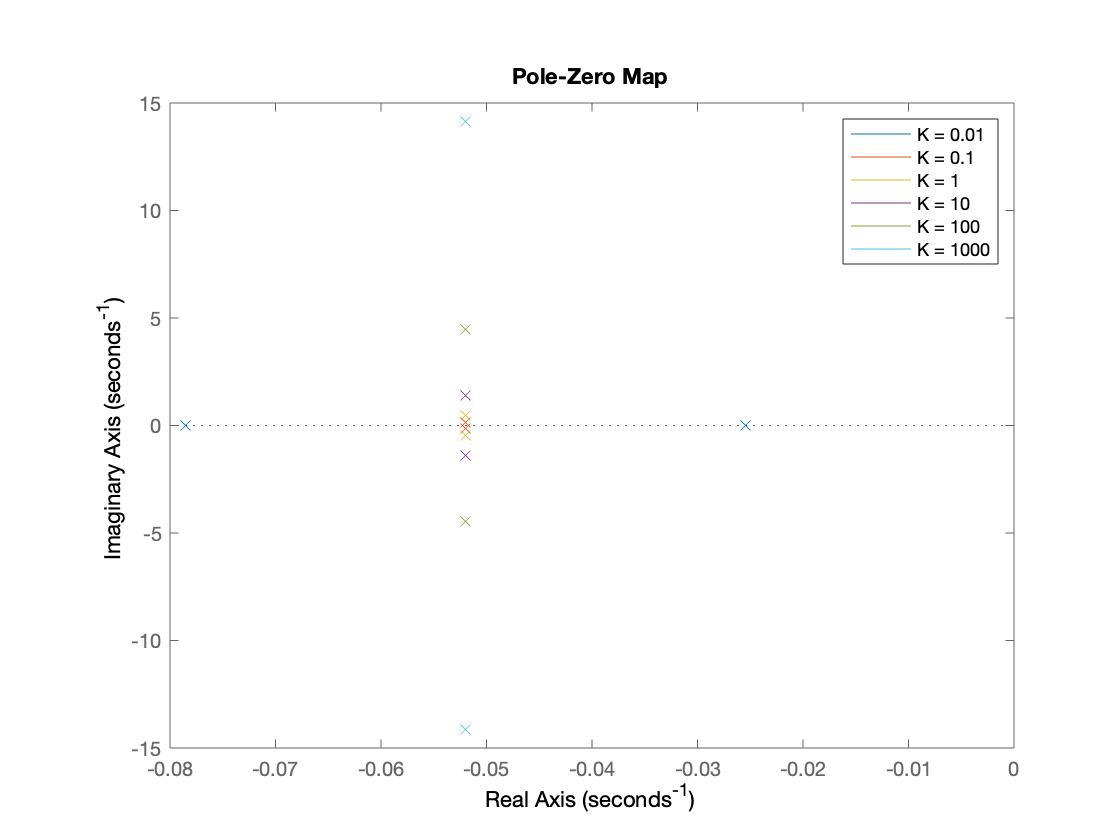


G = tf([b0], [1 a1 0]);
Gfb = feedback(G, 1)


Gk1 = feedback(G*K(1,1), 1);
Gk2 = feedback(G*K(1,2), 1);
Gk3 = feedback(G*K(1,3), 1);
Gk4 = feedback(G*K(1,4), 1);
Gk5 = feedback(G*K(1,5), 1);
Gk6 = feedback(G*K(1,6), 1);

p1 = pole(Gk1);
p2 = pole(Gk2);
p3 = pole(Gk3);
p4 = pole(Gk4);
p5 = pole(Gk5);
p6 = pole(Gk6);


pzplot(Gk1, Gk2, Gk3, Gk4, Gk5, Gk6)
legend("K = 0.01", "K = 0.1", "K = 1", "K = 10","K = 100","K = 1000");

3. Explain what root locus diagram describes and plot the root locus diagram for θ(s) as open va (s) loop function.[5 marks]

Hint: You can use command rlocus(sys) to plot the root locus diagram. Notice that this command receives the open loop system as input. 

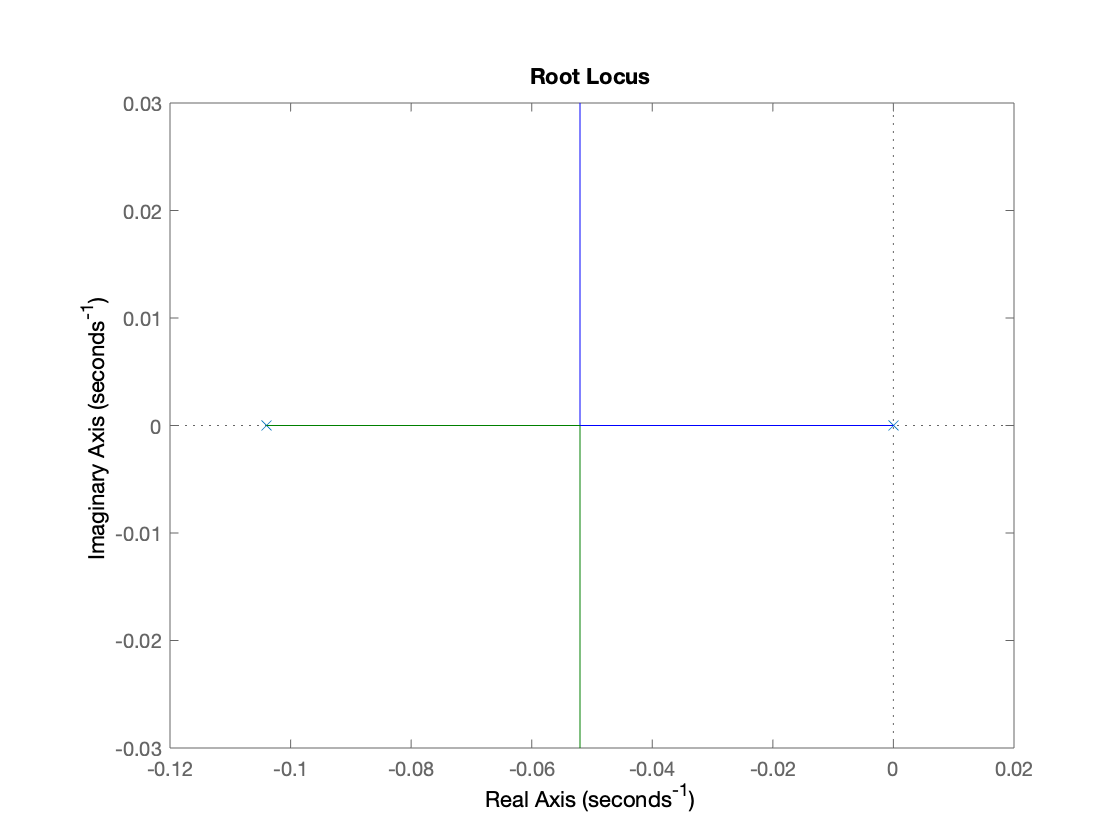

figure(1);
rlocus(G)
hold off;

4. Using the time-domain step response of second order systems find a value of proportional gain K such that closed loop step response has approximately 20% overshoot. Verify your proportional controller using step response of closed loop system.[10 marks]

Hint: You can use the formulas required in Question 4 and 5 from any reference. 

k = 0.01;
Gk = feedback(G*k, 1);
overshoot = stepinfo(Gk).Overshoot

overshoot = 0


while overshoot > 20.1 || overshoot < 19.9
    k = k + 0.005;
    Gk = feedback(G*k,1);
    overshoot = stepinfo(Gk).Overshoot;
   
end
overshoot

overshoot = 19.9891

k

k = 0.0650

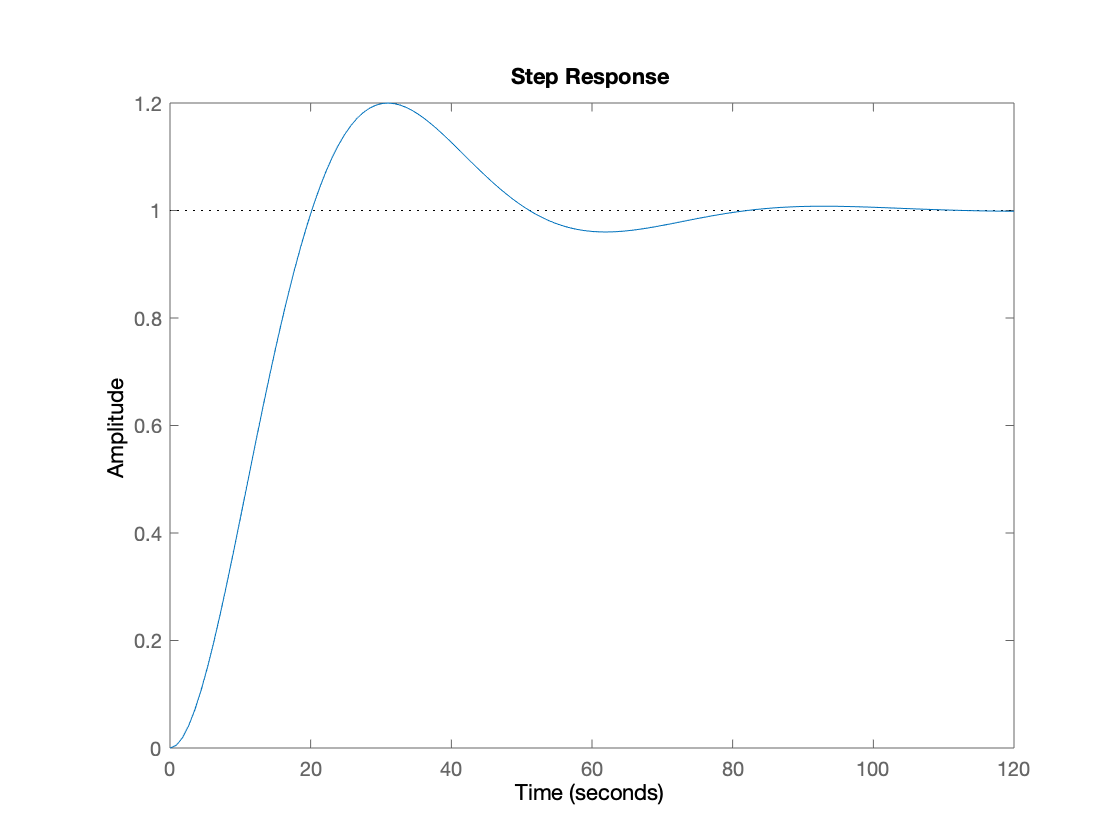

figure (1);
stepplot(Gk);

5. Ignoring the over shoot constraint in Question 4, find the proportional gain K such that closed loop step response has peak time of approximately 4s. Verify your proportional controller using step response of closed loop system.[10 marks] 						

k = 0.01;
Gk = feedback(G*k, 1);
peak_time = stepinfo(Gk).PeakTime;

while peak_time > 4.1 || peak_time < 3.9
    k = k + 0.005;
    Gk = feedback(G*k,1);
    peak_time = stepinfo(Gk).PeakTime;
   
end
peak_time

peak_time = 4.0970

k

k = 2.9400

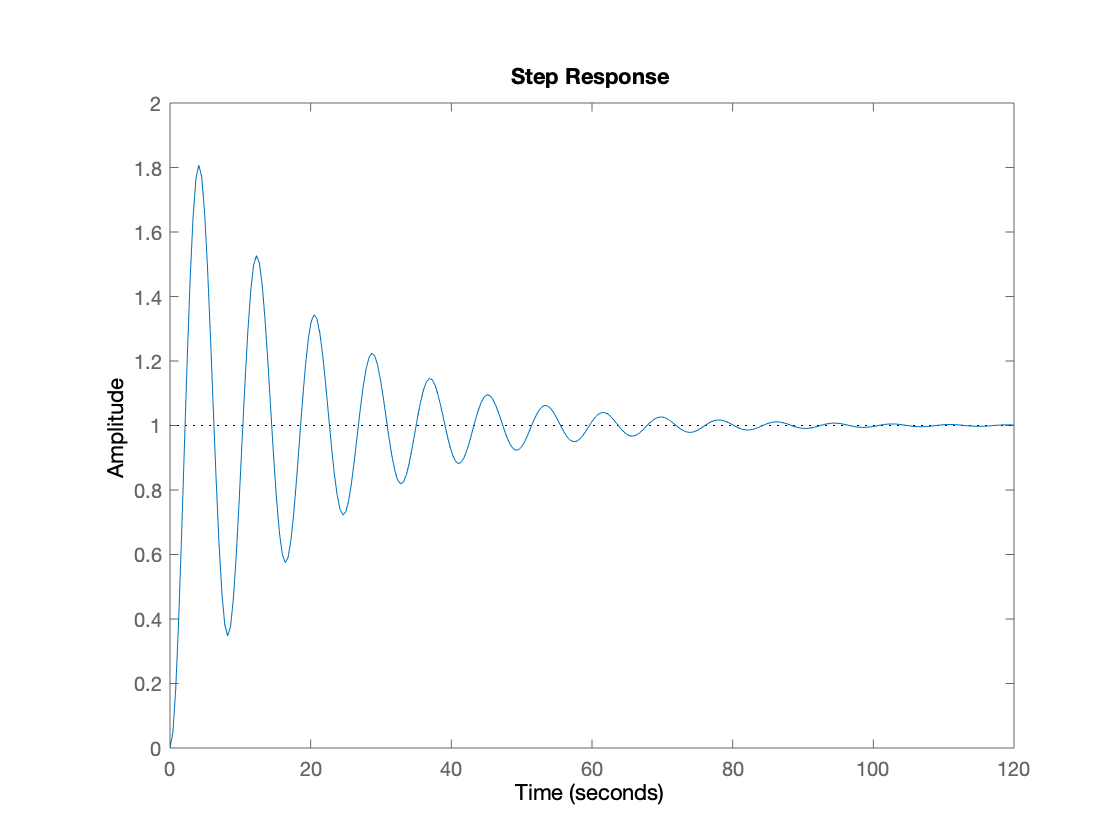

figure (2);
stepplot(Gk);

6.  Suppose a controller with transfer function (s+0.9) / (s+0.75 ) is  added to the system. Is there a proportional gain for this system which makes it unstable?[5 marks]

Gn = G*tf([1 0.9],[1 0.75])


Gn =
 
        0.2 s + 0.18
  -------------------------
  s^3 + 0.854 s^2 + 0.078 s
 
Continuous-time transfer function.



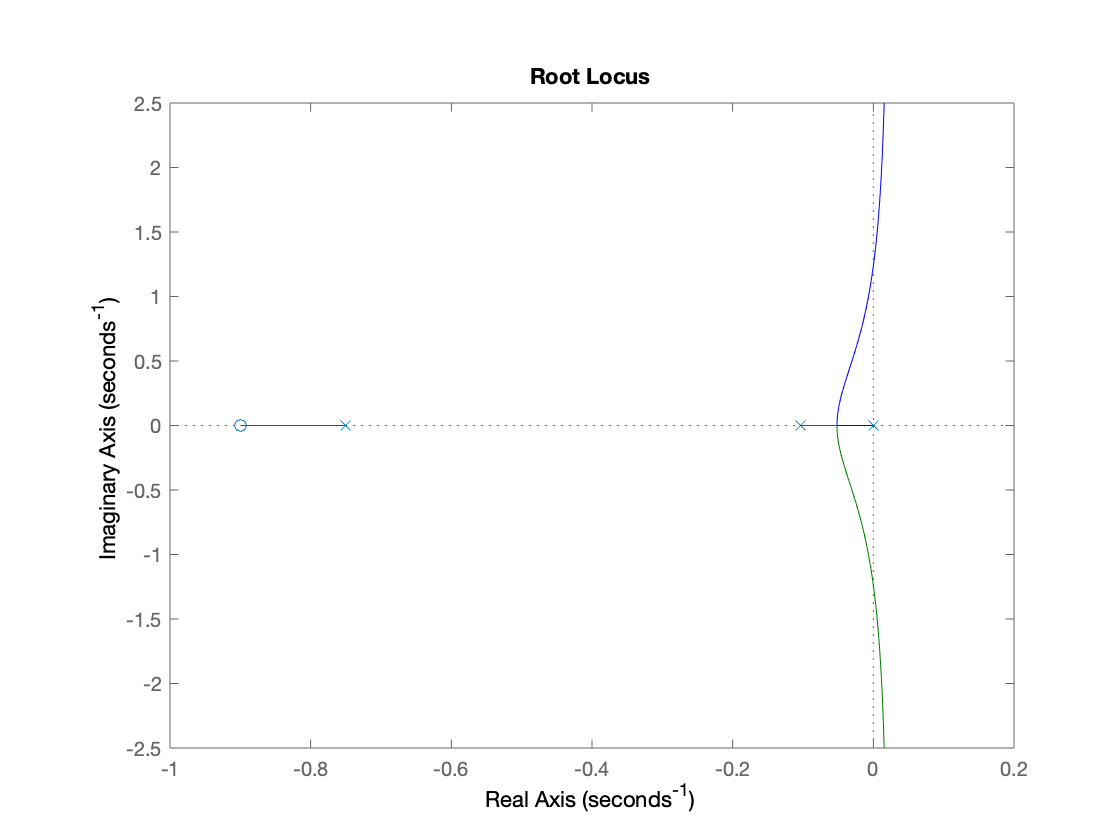

rlocus(Gn)

4.2 State Space Representation

7. The electormechanical equations of the DC motor can be described as following:

JmØ'' + bØ' = (Kt)i

(La)i' + (Ra)i = Va - KeØ'

where i and La = 0.5H are the current and inductance of the armature. The transfer function in Lab 1, is an approximation of the model which is described here. We can find the exact model of a DC motor by state space representation. Describe the state space representation of the DC motor in the standard form.  

La = 0.5;
D = 0;

(a) Variables (θ, ia) are assumed to be states of the system and variable θ is assumed to be the output.[5 marks]

(Please denote matrices corresponding to state space representation by A1, B1, C1.) 		

A1 = [-b/Jm Kt/Jm ; -Ke/La -Ra/La]

A1 =    -0.1000    2.0000
   -0.0400  -20.0000


B1 = [0 ; 1/La]

B1 =      0
     2


C1 = [1 0]

C1 =      1     0


b) Variables (θ,θ,ia) are assumed to be states of the system and variable θ is assumed to be the output.[5 marks]			

A2 = [0 1 0 ; 0 -b/Jm Kt/Jm ; 0 -Ke/La -Ra/La]

A2 =          0    1.0000         0
         0   -0.1000    2.0000
         0   -0.0400  -20.0000


B2 = [0 ; 0 ; 1/La]

B2 =      0
     0
     2


C2 = [1 0 0 ]

C2 =      1     0     0


8. Consider the state space model (A1,B1,C1). Find the transfer function(denote it by H1(s)) and plot the step response.[5 marks] 							 ̇Consider transfer function of θ'(s)/va(s) in Lab 1(denote it by G1(s)). Are transfer functions H1(S) and G1(s) exactly the same? Compare the step responses of H1(s) and G1(s), are they exactly the same?

[num,den] = ss2tf(A1,B1,C1,D);
H1 = tf(num, den)


H1 =
 
           4
  -------------------
  s^2 + 20.1 s + 2.08
 
Continuous-time transfer function.



G1 = tf([b0], [1 a1])


G1 =
 
     0.2
  ---------
  s + 0.104
 
Continuous-time transfer function.



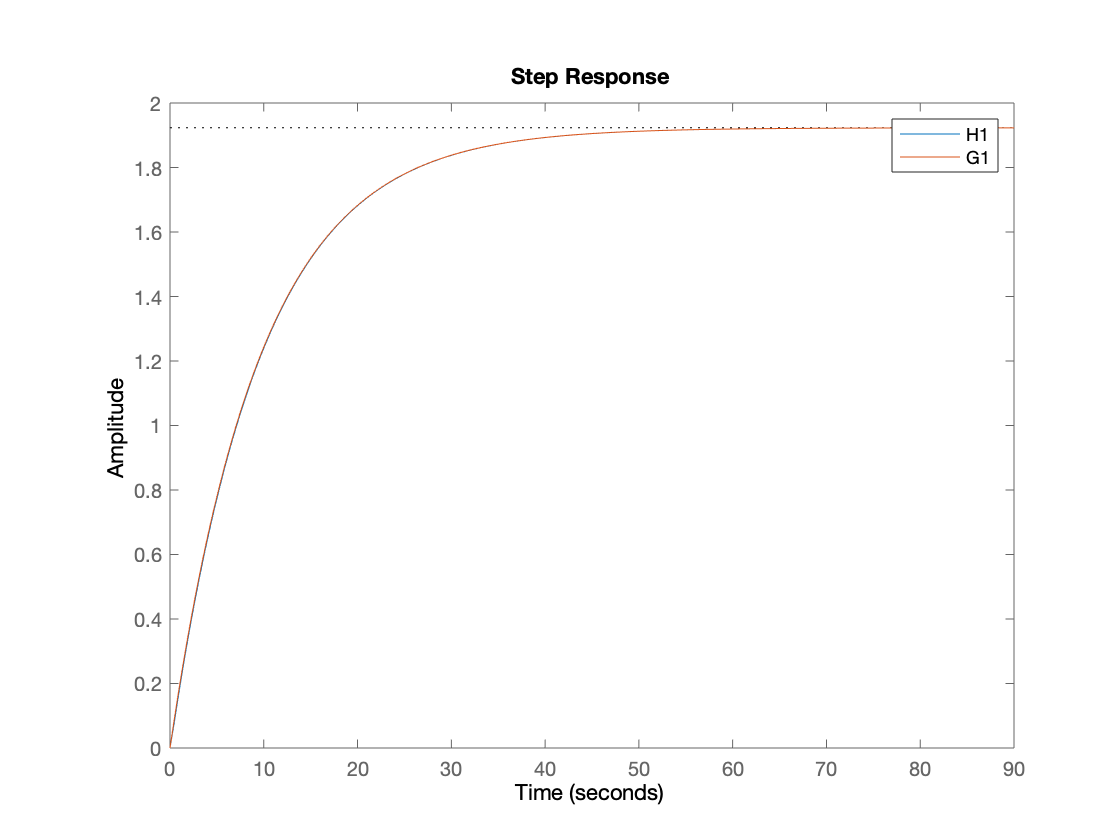


figure (3);
stepplot(H1);
hold on;
stepplot(G1);
legend("H1", "G1");
hold off ;

9. Graph the pole-zero plot for both H1(s) and G1(s). Based on these Graph explain why the approximation in Lab 1 was a ”good” approximation. [5 marks] 						 

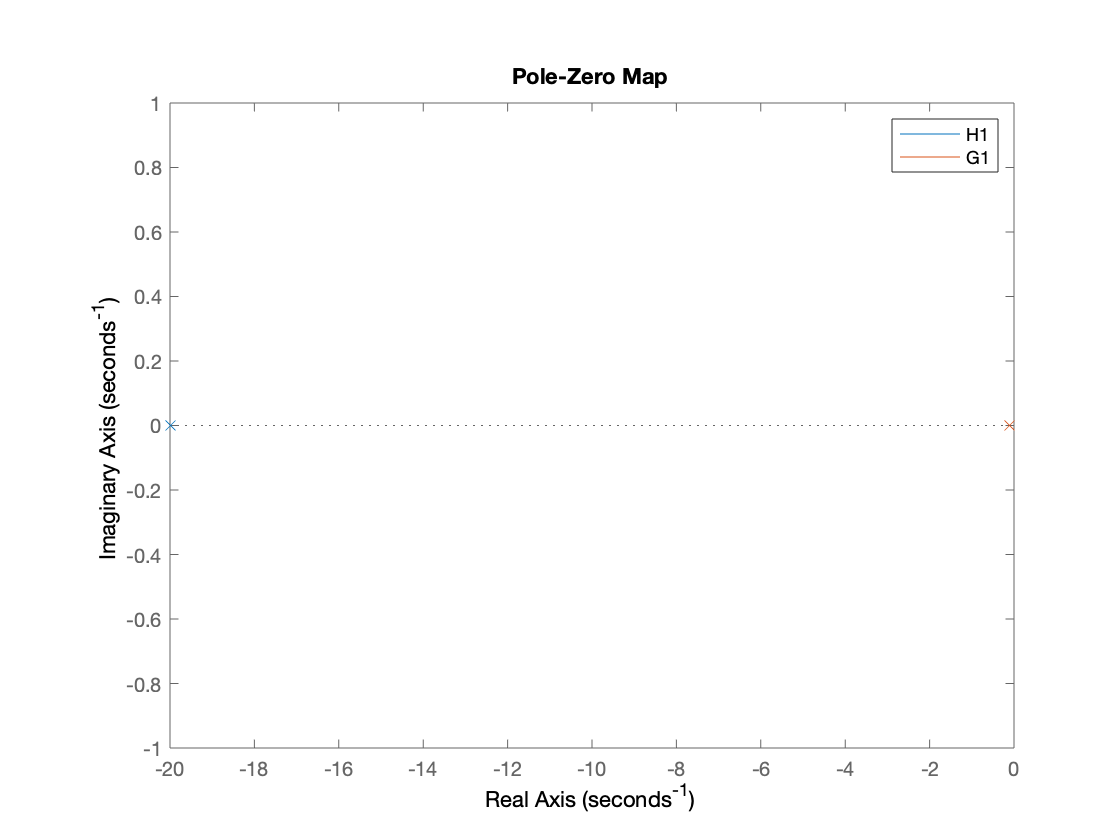

pzplot(H1, G1)
legend("H1", "G1");

10. Consider the state space model (A2,B2,C2). Find the transfer function(denote it by H2(s)) and plot the step response.[5 marks]Consider transfer function of θ(s)/va(s) in Lab 1(denote it by G2(s)). Are transfer functions H2(S) and G2(s) exactly the same? Compare the step responses of H2(s) and G2(s), are they exactly the same? [5 marks] 						

[num2,den2] = ss2tf(A2,B2,C2,D);
H2 = tf(num, den);
G2 = tf([b0], [1 a1 0])


G2 =
 
       0.2
  -------------
  s^2 + 0.104 s
 
Continuous-time transfer function.



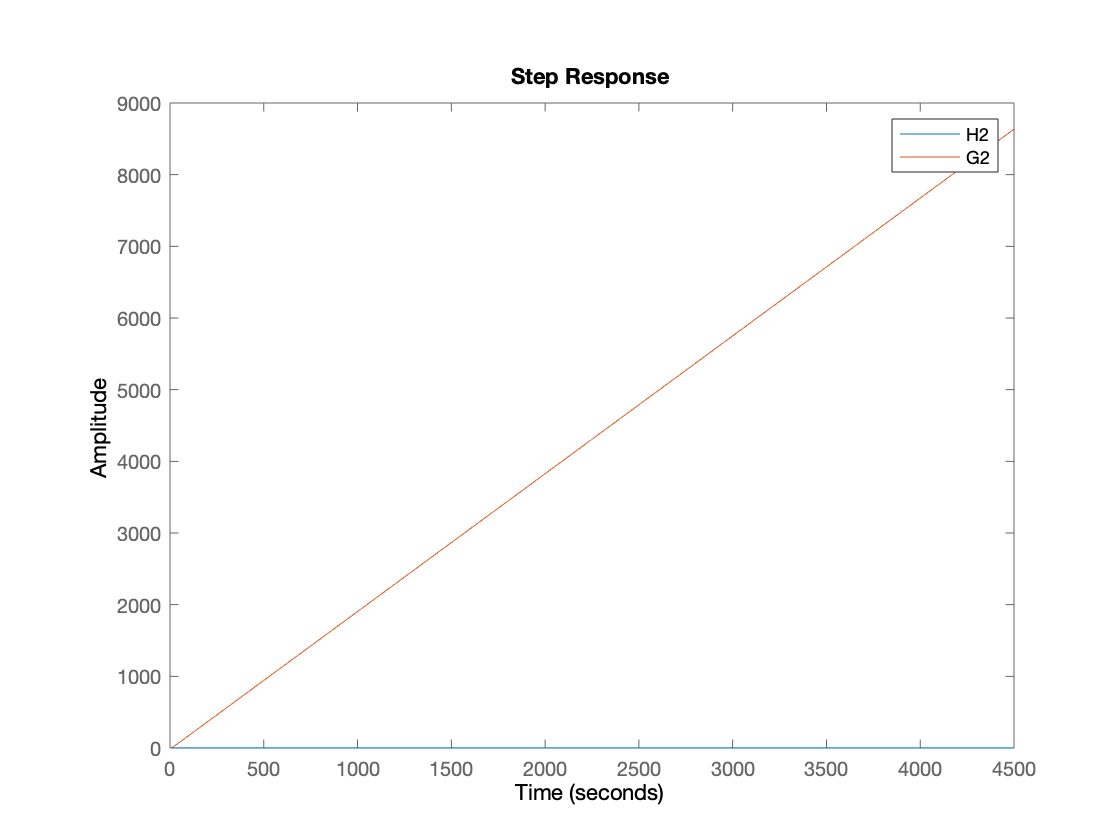


figure (4);
stepplot(H2);
hold on;
stepplot(G2);
legend("H2", "G2");
hold off ;

11. Graph the pole-zero plot for both H2(s) and G2(s). Based on these Graph explain why the approximation in Lab 1 was a ”good” approximation. [5 marks] 	

pzplot(H1, G1)
legend("H1", "G1");